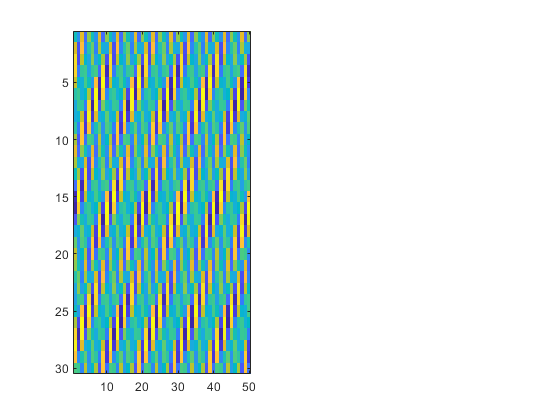

%% Part 1 : 1D FFT

% Generate Noisy Signal

% Specify the parameters of a signal with a sampling frequency of 1 kHz 
% and a signal duration of 1.5 seconds.

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector

% Form a signal containing a 50 Hz sinusoid of amplitude 0.7 and a 120 Hz 
% sinusoid of amplitude 1.

S = 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);

% Corrupt the signal with zero-mean white noise with a variance of 4
X = S + 2*randn(size(t));

% Plot the noisy signal in the time domain. It is difficult to identify
% the frequency components by looking at the signal X(t).

figure(1);
tiledlayout(1,2)

% left plot
nexttile
plot(1000*t(1:50), X(1:50))
title('Signal corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')

% Compute the Fourier Transform of the Signal.

Y = fft(X);

% Compute the 2 sided spectrum P2. Then compute the single-sided spectrum
% P1 based on P2 and the even-valued signal length L.

P2 = abs(Y/L);
P1 = P2(1:L/2+1);

% Define the frequency domain f and plot the single-sided amplitude 
% spectrum P1. The amplitudes are not exactly at 0.7 and 1, as expected,
% because of the added noise. On average, longer signals produce better 
% frequency approximations

f = Fs*(0:(L/2))/L;

nexttile
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

%% Part 2 - 2D FFT

% Implement a second FFT along the second dimension to determine the 
% doppler frequency shift.

% First we need to generate a 2D signal
% Convert 1D signal X to 2D using reshape

% while reshaping a 1D signal to 2D we need to ensure that dimensions match
% length(X) = M*N

% let
M = length(S)/50;
N = length(S)/30;
X_2d = reshape(S, [M, N]);

figure(2);
tiledlayout(1,2)

nexttile
imagesc(X_2d)



% TODO: Compute the 2-D Fourier transform of the data. 
Y_2d = fft2(X_2d)

Y_2d = 	1.0e+02 *

  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.6446 + 0.0406i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   2.2098 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.6446 - 0.0406i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i
   0.0000 - 0.0000i   0.0000 +


% Shift the zero-frequency component to the center of the output and plot the resulting 
% matrix, which is the same size as X_2d.
S1 = abs(fftshift(Y_2d))

S1 =     5.5435    0.0000    0.0000    0.0000    0.0000   25.5722    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   25.5722    0.0000    0.0000    0.0000    0.0000
    5.6062    0.0000    0.0000    0.0000    0.0000   24.6858    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   26.8295    0.0000    0.0000    0.0000    

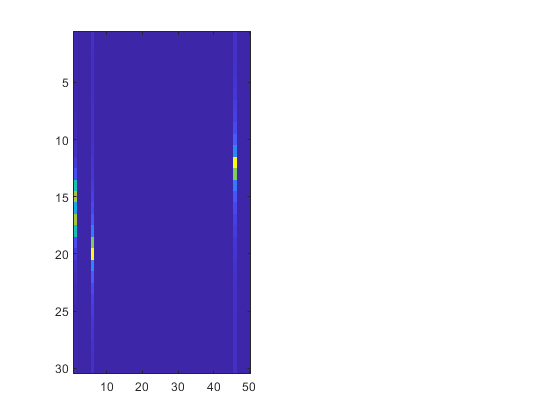

% TODO: plot here
imagesc(S1)